# Практическое задание 4.

Построить фильтр низких частот для изображений миры.

Оценить прострнственную частоту линий в зависимости от размера фильтров Низких частот.

Оценить среднее значение (mean2) среднеквадратичное отклонение(std2) для зашумлённых областей изображаения миры с помощью выделения фрагмента ROI.

Построить графики зависимости СКО от размера фильтра (plot).

а) Использовать фильтр типа:"Диск"

б) Использовать фильтр типа:"Гаусс"

в) Использовать фильтр типа:"Лапласиана"

г)*Использовать фильтр Баттерворта (butter)

Для работы можно использовать функцию if или switch

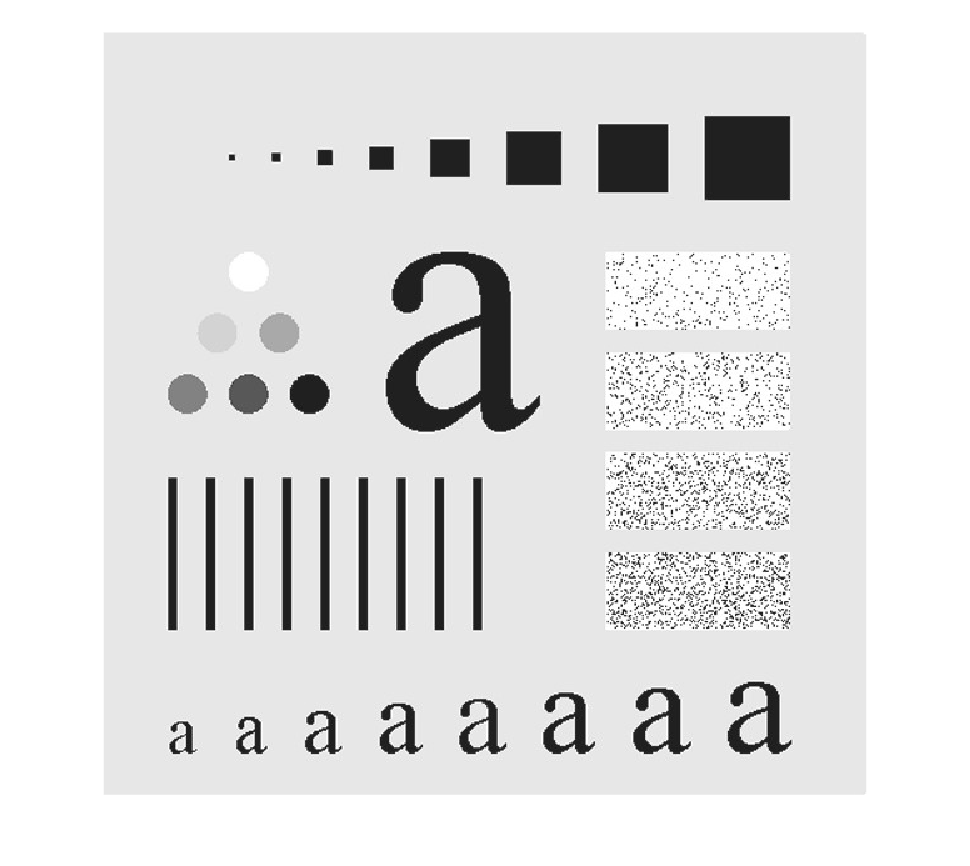

clc
clear
x ="Баттерворт";
Image = double(rgb2gray(imread("Мира.jpg")))/255;
Image_FFT = fft2(Image);
imshow(Image)

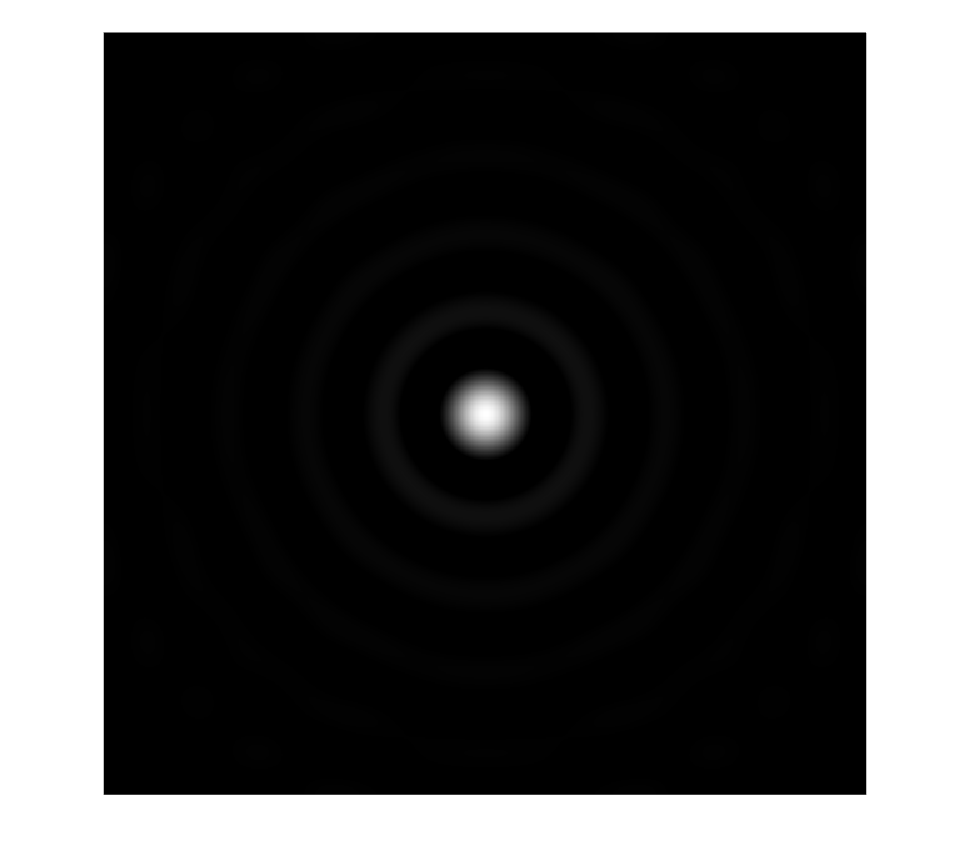

h =fspecial("disk",10);

% h =fspecial("gaussian",50,10);
h2 =psf2otf(h,[610,610]);
ImageNew =ifft2(Image_FFT.*h2);
imshow(fftshift(h2))

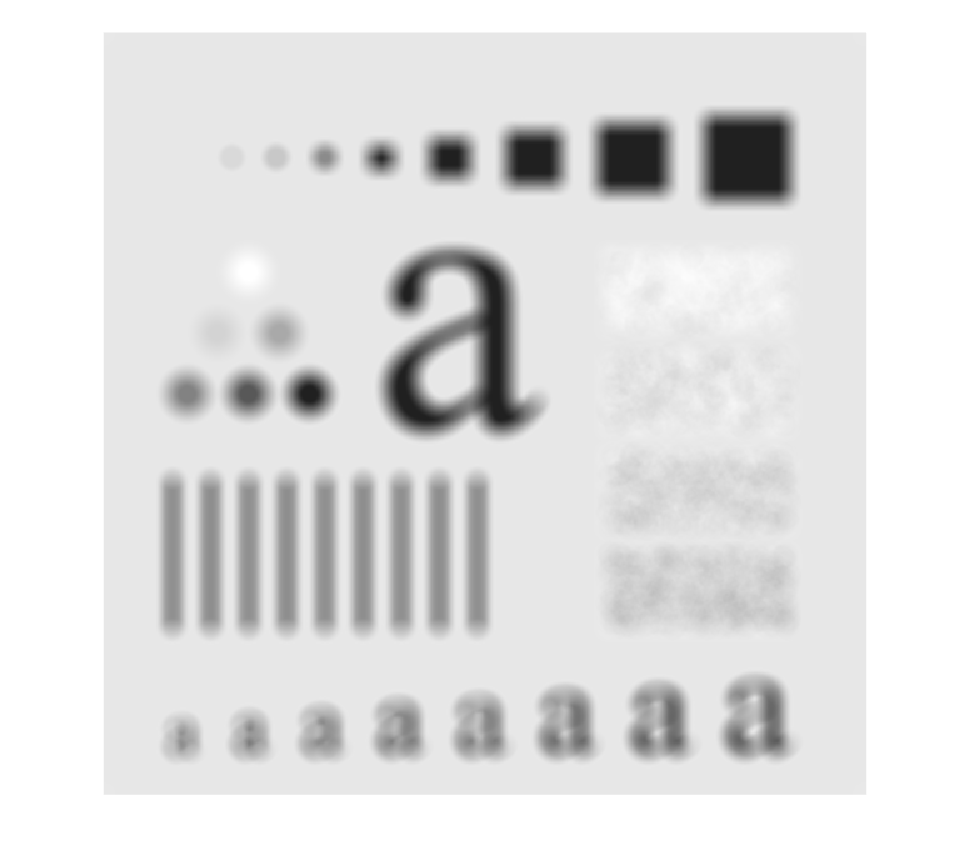

imshow(ImageNew)

imageSegmenter(Image)

mean(nonzeros(maskedImage.*Image))

ans = 0.8476

imageSegmenter(ImageNew)
mean(nonzeros(maskedImage1.*ImageNew))

ans = 0.8476

Построить фильтр высоких частот для изображений миры c помощью фильра типа "Диск" и функции padarray (нельзя использовать psf2otf).for